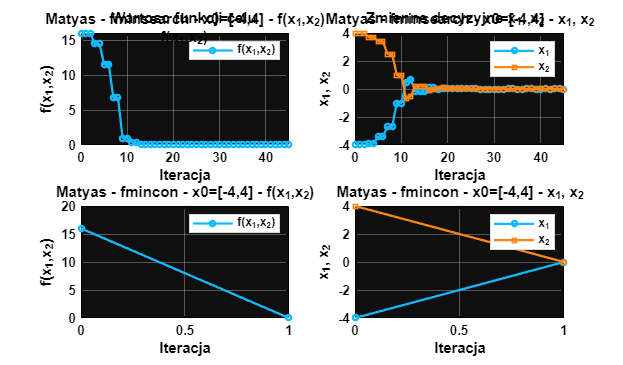

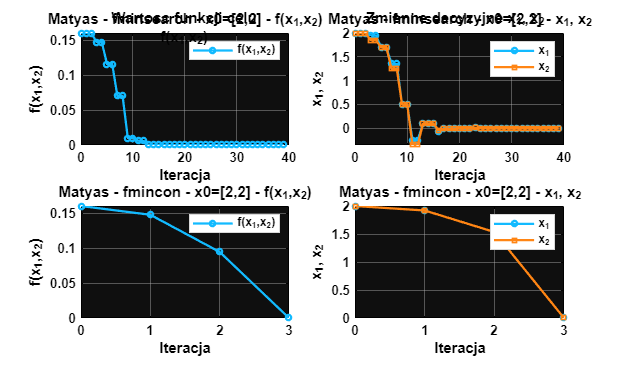

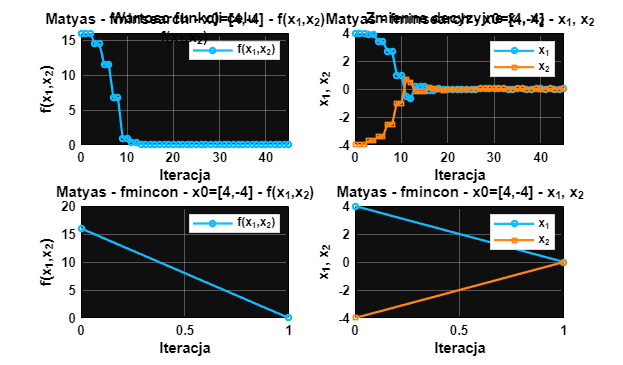

clear; clc; close all;

%% Funkcje testowe
f1 = @(x) 0.26*(x(1)^2+x(2)^2)-0.48*x(1)*x(2);
f2 = @(x) 0.5*(x(1)^4-16*x(1)^2+5*x(1)+x(2)^4-16*x(2)^2+5*x(2));
g1 = @(x) [0.52*x(1)-0.48*x(2); 0.52*x(2)-0.48*x(1)];
g2 = @(x) [2*x(1)^3-16*x(1)+2.5; 2*x(2)^3-16*x(2)+2.5];
H1 = @(x) [0.52 -0.48; -0.48 0.52];
H2 = @(x) [6*x(1)^2-16 0; 0 6*x(2)^2-16];

%% Parametry badania
funkcja = 1;   % 1 - Matyas, 2 - Styblinski-Tang
badanie = 1;   % 1 - x0, 2 - TolX, 3 - TolFun, 4 - MaxIter

if funkcja == 1
    f = f1; g = g1; H = H1; nazwa = 'Matyas';
    X0 = [-4 4; 2 2; 4 -4];
    xStale = [-4 4];
else
    f = f2; g = g2; H = H2; nazwa = 'Styblinski-Tang';
    X0 = [-4 -4; 4 4; -4 4];
    xStale = [4 4];
end

pola = ["Algorytm";"TolX";"TolFun";"MaxIter";"MaxFunEvals"; ...
        "x";"fval";"iteration";"Func-count";"First order optimality"; ...
        "Warunek stopu";"Gradient";"Hesjan";"Feasibility"];
T1 = strings(numel(pola),3);
T2 = strings(numel(pola),3);

%% Optymalizacja: trzy warianty
for k = 1:3
    x0a = X0(k,:); x0b = x0a;
    os = optimset('fminsearch');
    oc = optimoptions('fmincon','Algorithm','interior-point','Display','off');
    ts = [1e-4 1e-4 400 400];
    tc = [1e-10 1e-6 1000 3000];

    if badanie > 1
        x0a = xStale; x0b = xStale;
        ts = [1e-6 1e-6 500 5000];
        tc = [1e-6 1e-6 500 5000];
        if badanie == 2
            wart = [1e-3 1e-4 1e-6];
            ts(1) = wart(k); tc(1) = wart(k);
        elseif badanie == 3
            wart = [1e-3 1e-6 1e-9];
            ts(2) = wart(k); tc(2) = wart(k);
        else
            limity = [2 10 100];
            ts(3) = limity(k); tc(3) = limity(k);
            if funkcja == 1
                limityC = [1 2 10];
                tc(3) = limityC(k);
                x0b = [2 2];
            end
        end
        os = optimset(os,'TolX',ts(1),'TolFun',ts(2), ...
            'MaxIter',ts(3),'MaxFunEvals',ts(4));
        oc = optimoptions(oc,'StepTolerance',tc(1), ...
            'OptimalityTolerance',tc(2),'MaxIterations',tc(3), ...
            'MaxFunctionEvaluations',tc(4));
    end

    os = optimset(os,'Display','off','OutputFcn',@historia);
    oc = optimoptions(oc,'OutputFcn',@historia);

    [xs,fs,flags,outs] = fminsearch(f,x0a,os);
    hs = historia();
    hs = [0 x0a f(x0a); hs(hs(:,1)>0,:)];

    [xc,fc,flagc,outc] = fmincon(f,x0b,[],[],[],[],[],[],[],oc);
    hc = historia();
    hc = [0 x0b f(x0b); hc(hc(:,1)>0,:)];

    T1(:,k) = zapis('Nelder-Mead',ts,xs,fs,flags,outs,g(xs),H(xs),'nie dotyczy');
    T2(:,k) = zapis('interior-point',tc,xc,fc,flagc,outc,g(xc),H(xc),'0');

    if badanie == 1
        opisS = sprintf('x0=[%g,%g]',x0a(1),x0a(2));
        opisC = sprintf('x0=[%g,%g]',x0b(1),x0b(2));
    elseif badanie == 2
        opisS = sprintf('TolX=%.5g',ts(1));
        opisC = sprintf('TolX=%.5g',tc(1));
    elseif badanie == 3
        opisS = sprintf('TolFun=%.5g',ts(2));
        opisC = sprintf('TolFun=%.5g',tc(2));
    else
        opisS = sprintf('MaxIter=%g',ts(3));
        opisC = sprintf('MaxIter=%g',tc(3));
    end

    figure('Color','w','Position',[100 100 1450 850]);
    rysuj(hs,hc,nazwa,opisS,opisC);
end


%% Tabele wynikow
fprintf('\n%s - fminsearch\n',nazwa);


Matyas - fminsearch


disp(table(pola,T1(:,1),T1(:,2),T1(:,3), ...
    'VariableNames',{'Parametr','Wariant_1','Wariant_2','Wariant_3'}));

            Parametr                     Wariant_1                       Wariant_2                       Wariant_3          
    ________________________    ____________________________    ____________________________    ____________________________

    "Algorytm"                  "Nelder-Mead"                   "Nelder-Mead"                   "Nelder-Mead"               
    "TolX"                      "0.0001"                        "0.0001"                        "0.0001"                    
    "TolFun"                    "0.0001"                        "0.0001"                        "0.0001"                    
    "MaxIter"                   "400"                           "400"                           "400"                       
    "MaxFunEvals"               "400"                           "400"                           "400"            

fprintf('\n%s - fmincon\n',nazwa);


Matyas - fmincon


disp(table(pola,T2(:,1),T2(:,2),T2(:,3), ...
    'VariableNames',{'Parametr','Wariant_1','Wariant_2','Wariant_3'}));

            Parametr                          Wariant_1                                Wariant_2                                Wariant_3              
    ________________________    _____________________________________    _____________________________________    _____________________________________

    "Algorytm"                  "interior-point"                         "interior-point"                         "interior-point"                     
    "TolX"                      "1e-10"                                  "1e-10"                                  "1e-10"                              
    "TolFun"                    "1e-06"                                  "1e-06"                                  "1e-06"                              
    "MaxIter"                   "1000"                                   "1000"                        


function [stop,h] = historia(x,ov,state)
persistent wyniki
stop = false;
if nargin == 0
    stop = wyniki;
    h = [];
    return
end
if strcmp(state,'init')
    wyniki = [0 x(:).' ov.fval];
elseif strcmp(state,'iter')
    p = [ov.iteration x(:).' ov.fval];
    if p(1) > wyniki(end,1)
        wyniki(end+1,:) = p;
    else
        wyniki(end,:) = p;
    end
end
h = [];
end

function w = zapis(alg,tol,x,fval,flag,out,grad,H,feas)
if flag == 0
    if out.iterations >= tol(3)
        stop = 'Limit iteracji';
    else
        stop = 'Limit wywolan';
    end
elseif flag == 2
    stop = 'Mala zmiana x';
elseif strcmp(alg,'Nelder-Mead')
    stop = 'TolX i TolFun';
else
    stop = 'Kryterium optymalnosci';
end
w = [string(alg); string(tol(1)); string(tol(2)); string(tol(3)); ...
    string(tol(4)); string(mat2str(x,6)); string(sprintf('%.9g',fval)); ...
    string(out.iterations); string(out.funcCount); ...
    string(sprintf('%.5g',max(abs(grad)))); ...
    string(sprintf('%s (exitflag=%d)',stop,flag)); ...
    string(mat2str(grad(:).',5)); string(mat2str(H,5)); string(feas)];
end

function rysuj(hs,hc,nazwa,opisS,opisC)
kolor1 = [0.07 0.73 1.00];
kolor2 = [1.00 0.52 0.08];

subplot(2,2,1);
plot(hs(:,1),hs(:,4),'-o','Color',kolor1,'LineWidth',1.7,'MarkerSize',4); grid on;
title(sprintf('%s - fminsearch - %s - f(x_1,x_2)',nazwa,opisS), ...
    'Color','k','FontWeight','bold','FontSize',10);
ylabel('f(x_1,x_2)','Color','k','FontWeight','bold');
xlabel('Iteracja','Color','k','FontWeight','bold');
legend('f(x_1,x_2)','TextColor','k','Color','w','Location','northeast');

subplot(2,2,2);
plot(hs(:,1),hs(:,2),'-o','Color',kolor1,'LineWidth',1.7,'MarkerSize',4); hold on;
plot(hs(:,1),hs(:,3),'-s','Color',kolor2,'LineWidth',1.7,'MarkerSize',4); grid on;
title(sprintf('%s - fminsearch - %s - x_1, x_2',nazwa,opisS), ...
    'Color','k','FontWeight','bold','FontSize',10);
ylabel('x_1, x_2','Color','k','FontWeight','bold');
xlabel('Iteracja','Color','k','FontWeight','bold');
legend('x_1','x_2','TextColor','k','Color','w','Location','northeast');

subplot(2,2,3);
plot(hc(:,1),hc(:,4),'-o','Color',kolor1,'LineWidth',1.7,'MarkerSize',4); grid on;
title(sprintf('%s - fmincon - %s - f(x_1,x_2)',nazwa,opisC), ...
    'Color','k','FontWeight','bold','FontSize',10);
ylabel('f(x_1,x_2)','Color','k','FontWeight','bold');
xlabel('Iteracja','Color','k','FontWeight','bold');
legend('f(x_1,x_2)','TextColor','k','Color','w','Location','northeast');

subplot(2,2,4);
plot(hc(:,1),hc(:,2),'-o','Color',kolor1,'LineWidth',1.7,'MarkerSize',4); hold on;
plot(hc(:,1),hc(:,3),'-s','Color',kolor2,'LineWidth',1.7,'MarkerSize',4); grid on;
title(sprintf('%s - fmincon - %s - x_1, x_2',nazwa,opisC), ...
    'Color','k','FontWeight','bold','FontSize',10);
ylabel('x_1, x_2','Color','k','FontWeight','bold');
xlabel('Iteracja','Color','k','FontWeight','bold');
legend('x_1','x_2','TextColor','k','Color','w','Location','northeast');

for ax = findall(gcf,'Type','axes')'
    ax.Color = [0.06 0.06 0.06];
    ax.XColor = [0 0 0]; ax.YColor = [0 0 0];
    ax.GridColor = [.72 .72 .72]; ax.GridAlpha = .42;
    ax.FontSize = 10; ax.FontWeight = 'bold';
    ax.Box = 'on';
    ax.Title.Color = [0 0 0];
    ax.XLabel.Color = [0 0 0]; ax.YLabel.Color = [0 0 0];
end

annotation('textbox',[.13 .954 .33 .033], ...
    'String','Wartosc funkcji celu f(x_1,x_2)', ...
    'Interpreter','tex','EdgeColor','none', ...
    'HorizontalAlignment','center','FontWeight','bold', ...
    'FontSize',11,'Color','k');
annotation('textbox',[.56 .954 .34 .033], ...
    'String','Zmienne decyzyjne x_1, x_2', ...
    'Interpreter','tex','EdgeColor','none', ...
    'HorizontalAlignment','center','FontWeight','bold', ...
    'FontSize',11,'Color','k');
end
